# Questions_1_and_2.mlx

clc
clear all
close all

## Question number 1

%% Part 1
N = 1024; %The sample rate
omega = linspace(0,pi,2049);

% The value of the variance according to the analytical calculation
sigma1 = 1/sqrt(26);
sigma2 = sqrt(0.51);

% The value of the spectrom according to the analytical calculation
S_x1_Analytic = 1 + 9/13*(cos(omega)) -4/13*(cos(2*omega));
S_x2_Analytic = 0.51./(1.49-1.4*cos(omega));


## Question number 2

Section 1


% Generate the signals w1(n) & x1(n)
w1 = sigma1*randn(1,N);
x1 = filter([1,-3,-4],1,w1);

% Generate the signals w2(n) & x2(n)
w2 = sigma2*randn(1,2*N);
x2_2048 = filter(1,[1,-0.7],w2);
x2 = x2_2048(N+1:2*N);

% Alternative Generation of x2(n)
w2_alternative = sigma2*randn(1,N);
x2_alternative(1) = randn(1);
for n = 2:N
    x2_alternative(n) = 0.7*x2_alternative(n-1) + w2_alternative(n);
end

Section 2

M = 4096;

%X_1 Periodgram
x1_zp = [x1 zeros(1,M-N)];
X_1 = fft(x1_zp);
S_x1_periodgram = (1/N)*(X_1(1:M/2+1)).*conj(X_1(1:M/2+1));

Section 3

%X_1 Correlogram
R_x1 = xcorr(x1)./N;

R_x1_zp = [R_x1(N:2*N-1) zeros(1,M/2+3) R_x1(1:N-1)];
S_x1 = fft(R_x1_zp);
S_x1_correlogram = S_x1(1:2*N+1);

Section 4

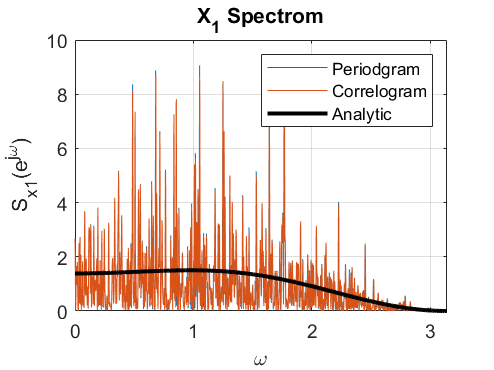

% Sections 2 and 3 for the signal x2
%X_2 Periodgram
x2_zp = [x2 zeros(1,M-N)];
X_2 = fft(x2_zp);
S_x2_periodgram = (1/N)*(X_2(1:M/2+1)).*conj(X_2(1:M/2+1));

%X_2 Correlogram
R_x2 = xcorr(x2)./N;

R_x2_zp = [R_x2(N:2*N-1) zeros(1,M/2+3) R_x2(1:N-1)];
S_x2 = fft(R_x2_zp);
S_x2_correlogram = S_x2(1:2*N+1);

%plot
%max(imag(S_x1_correlogram))
figure(1)
plot(omega,S_x1_periodgram);
hold on
plot(omega,real(S_x1_correlogram));
plot(omega, S_x1_Analytic, 'k', 'LineWidth',2);
grid on
title('X_1 Spectrom')
ylabel('S_x_1(e^j^\omega)')
xlabel('\omega')
legend('Periodgram', 'Correlogram', 'Analytic')

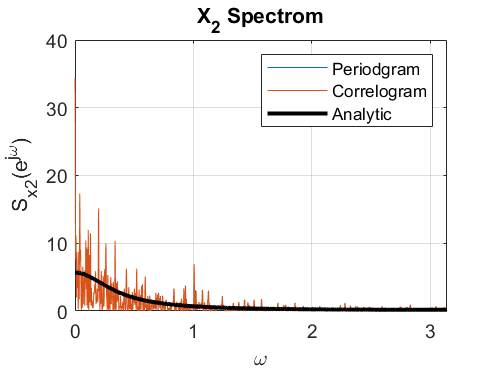


%max(imag(S_x2_correlogram))
figure(2)
plot(omega,S_x2_periodgram);
hold on
plot(omega,real(S_x2_correlogram));
plot(omega, S_x2_Analytic, 'k', 'LineWidth',2);
grid on
title('X_2 Spectrom')
ylabel('S_x_2(e^j^\omega)')
xlabel('\omega')
legend('Periodgram', 'Correlogram', 'Analytic')